# Digit classification: reducing feature space dimensionality

The `extractDigitData()` function, below, is a helper function which lets you extract `features` and `labels` from collections of images showing handwritten digits between 1-9. You can use it to read either a set of training images or testing images (see the first argument `dataset`), and to extract differently sized HOG features (see the second argument `cellSize`).

The code immediately below calls the `extractDigitData()` function to extract 4*4 pixel HOG features from the training set, uses them to train a classifier and then uses that classifier to predict labels for the testing set. Check you can understand the code, and run it before answering the questions below.

The challenge here is to investigate using smaller HOG features while keeping the dimensionality of the feature space constant using PCA.

Marks are available for:

- Finding the dimensionality of the feature space that results from the images and recording it in a comment [1 mark]

- Calculating the classifier's overall classification accuracy [1 mark]

- Training a *second* classifier (again using `fitcecoc()`) based on 2*2 pixel HOG features [2 marks]

- Finding the dimensionality of the feature space that results from the images and recording it in a comment [1 mark]

- Calculating the second classifier's overall classification accuracy [1 mark]

- Using PCA to reduce the dimensionality of your new feature space down to match the dimensionality of your original feature space. As all the features are HOG features you *don't* need to perform z-score standardisation [5 marks]

- Using the results to train a *third* classifier (again using `fitcecoc()`) [4 marks]

- Extracting 2*2 pixel HOG features from the test images, shifting them into your new space, classifying them using your third classifier and briefly commenting on the resulting classification accuracy in a comment [5 marks]

[20 marks]

% extract training data:
[train_examples, train_labels] = extractDigitData('train', [4 4]);
% train a classifier:
classifier = fitcecoc(train_examples, train_labels);
% extract test data:
[test_examples, test_labels] = extractDigitData('test', [4 4]);
% make predictions:
predicted = predict(classifier, test_examples);
predicted(1:25)

ans = 25×1 categorical array
     8 
     6 
     0 
     6 
     0 
     6 
     6 
     6 
     6 
     2 
     0 
     6 
     1 
     1 
     1 
     1 
     7 
     4 
     1 
     1 
     1 
     1 
     1 
     8 
     2 


% add as many lines of code as you need below:
[c,order] = confusionmat(test_labels, predicted);

c =      3     0     1     0     0     0     7     0     1     0
     0     9     0     0     1     0     0     1     1     0
     0     0     8     2     0     0     1     0     0     1
     0     0     0     7     0     0     4     0     0     1
     0     1     0     2     9     0     0     0     0     0
     0     0     0     0     0     4     7     0     1     0
     0     0     0     0     3     0     8     0     1     0
     0     1     1     4     0     0     2     3     0     1
     0     0     0     1     0     0     0     1     8     2
     0     1     0     3     2     0     1     0     0     5


order = 10×1 categorical array
     0 
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 


my_p = sum(diag(c)) / sum(c(1:1:end));

my_p = 0.5333

%accuracy was 53.3%

[train_examples, train_labels] = extractDigitData('train', [2 2]);
classifier = fitcecoc(train_examples, train_labels);
[test_examples, test_labels] = extractDigitData('test', [2 2]);
predicted = predict(classifier, test_examples);

predicted(1:25)

ans = 25×1 categorical array
     6 
     6 
     6 
     6 
     0 
     6 
     6 
     6 
     6 
     2 
     0 
     6 
     1 
     1 
     1 
     1 
     7 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     2 


% add as many lines of code as you need below:
[c,order] = confusionmat(test_labels, predicted)

c =      2     0     1     0     0     0     9     0     0     0
     0    11     0     0     0     0     0     1     0     0
     1     1     9     0     0     0     0     0     0     1
     0     0     0     8     0     0     2     1     0     1
     1     0     0     0    10     0     1     0     0     0
     0     0     0     1     0     6     5     0     0     0
     0     1     0     0     0     0    10     1     0     0
     1     1     0     0     1     0     0     8     0     1
     0     0     0     1     1     0     1     2     6     1
     0     2     0     0     2     3     1     0     0     4


order = 10×1 categorical array
     0 
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 


my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.6167

%accuracy was 61.7%




[principal_components, data_transformed, ~, ~, explained] = pca(train_examples)

principal_components = 1764×1009 single matrix
    0.0087   -0.0091   -0.0015   -0.0061    0.0010   -0.0032    0.0201   -0.0054    0.0002   -0.0142   -0.0028    0.0263    0.0519    0.0064    0.0087   -0.0483   -0.1126   -0.0487   -0.0365   -0.0112   -0.0057   -0.0630   -0.0063   -0.0594    0.0322    0.0118   -0.0156   -0.0078    0.0034    0.0205    0.0110    0.0386   -0.0433   -0.0774   -0.0274   -0.0105    0.0523    0.0178   -0.0040    0.0298   -0.0253   -0.0081   -0.0160    0.0163   -0.0360    0.0228    0.0208    0.0046    0.0138   -0.0178
    0.0020   -0.0012   -0.0008   -0.0016    0.0009   -0.0036    0.0045   -0.0070    0.0014   -0.0056    0.0049   -0.0092    0.0010   -0.0020   -0.0028    0.0055    0.0100    0.0127    0.0135    0.0048   -0.0010    0.0045   -0.0028   -0.0329   -0.0316   -0.0155    0.0078   -0.0044   -0.0286    0.0133   -0.0108    0.0028    0.0209    0.0028    0.0218    0.0062    0.0010   -0.0020   -0.0101    0.0148    0.0125   -0.0027    0.0116   -0.0085    0.0074  

data_transformed = 1010×1009 single matrix
    1.9205   -0.2863    1.7256    0.3001   -0.3848   -1.4834   -1.3468   -0.0215   -0.2447    0.1557   -1.1453   -0.7923   -0.1002   -0.3426    0.2853    0.5055   -0.3496   -0.5430   -0.5273    0.6142    0.0379   -0.1160    0.3525    0.3301   -0.1073   -0.5116   -0.0108   -0.7088   -0.8288    0.2991   -0.3076   -0.3070   -0.5193    0.1993   -0.2768   -0.4363   -0.5882   -0.3366   -0.2557   -0.0380   -0.0820   -0.0810    0.0609   -0.1752   -0.1769   -0.3176    0.3065   -0.1228   -0.4075   -0.6981
    0.8834    0.8505    1.1470   -1.3520    0.8131   -1.3489   -1.4409    0.4013   -0.3740   -0.2702   -0.3287    0.8096   -0.0677    1.4263    0.1238   -0.4453    0.5049    0.7356   -0.5400   -0.4930   -0.0941   -0.2355   -0.3242   -0.1238    0.5679    0.3668    0.3979   -0.5406   -0.1515   -0.8454   -0.2761   -0.4245    0.4771    0.0305    0.0839    0.4097    0.0681    0.1809   -0.0526   -0.2684   -0.2124    0.5450   -0.3395   -0.2634   -0.1861   -0.

explained = 1009×1 single column vector
   11.3237
    8.8396
    7.5804
    6.1686
    5.8124
    5.1659
    4.5494
    4.3508
    3.3665
    3.1849


examples_test_new = train_examples * principal_components

examples_test_new = 1010×1009 single matrix
    3.0537    0.1831    2.2878    0.0947    0.3892   -1.7386   -0.5219   -0.1195   -0.1187   -0.5545   -0.4644    0.2818    0.0495   -0.1870    0.4004    0.3274   -0.1113   -0.5076   -0.1310    0.6603   -0.1730   -0.0376    0.1910    0.0277   -0.5812   -0.1473   -0.1719   -0.0848    0.0075    0.6102   -0.0951    0.1271   -0.1206    0.0143   -0.1942   -0.1225   -0.7215   -0.3546   -0.0556   -0.3620    0.0652    0.6726    0.8204    0.6692   -0.1537    0.0444   -0.0215   -0.2938   -0.2568   -0.3070
    2.0166    1.3199    1.7092   -1.5574    1.5872   -1.6041   -0.6160    0.3034   -0.2481   -0.9804    0.3521    1.8837    0.0820    1.5820    0.2389   -0.6234    0.7432    0.7711   -0.1437   -0.4468   -0.3050   -0.1572   -0.4857   -0.4262    0.0940    0.7312    0.2368    0.0833    0.6848   -0.5343   -0.0636    0.0096    0.8758   -0.1544    0.1665    0.7235   -0.0652    0.1629    0.1476   -0.5924   -0.0652    1.2986    0.4200    0.5810   -0.1629    0

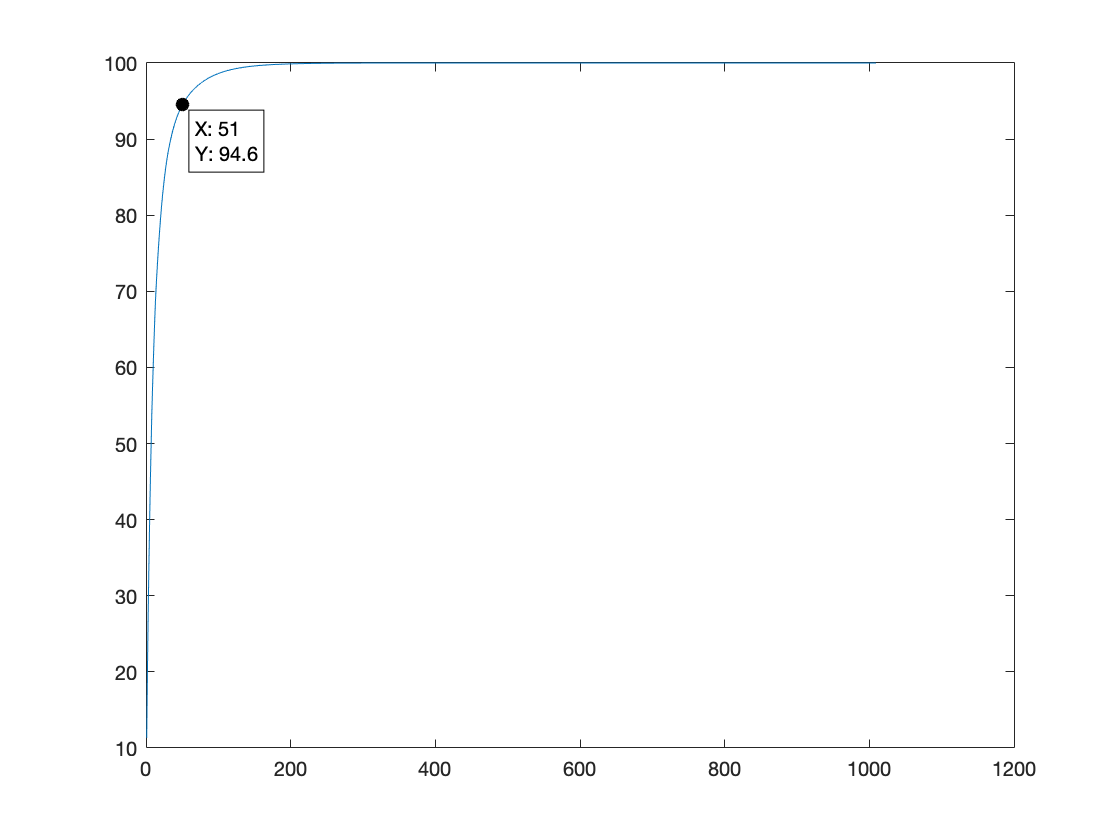

%plotting the graph for the pc's
plot(cumsum(explained));

%I’ll keep the first 53 PCs in order to explain at least 95% of the variance in my training data
data_reduced = examples_test_new(:, 1:1:53)

data_reduced = 1010×53 single matrix
    3.0537    0.1831    2.2878    0.0947    0.3892   -1.7386   -0.5219   -0.1195   -0.1187   -0.5545   -0.4644    0.2818    0.0495   -0.1870    0.4004    0.3274   -0.1113   -0.5076   -0.1310    0.6603   -0.1730   -0.0376    0.1910    0.0277   -0.5812   -0.1473   -0.1719   -0.0848    0.0075    0.6102   -0.0951    0.1271   -0.1206    0.0143   -0.1942   -0.1225   -0.7215   -0.3546   -0.0556   -0.3620    0.0652    0.6726    0.8204    0.6692   -0.1537    0.0444   -0.0215   -0.2938   -0.2568   -0.3070
    2.0166    1.3199    1.7092   -1.5574    1.5872   -1.6041   -0.6160    0.3034   -0.2481   -0.9804    0.3521    1.8837    0.0820    1.5820    0.2389   -0.6234    0.7432    0.7711   -0.1437   -0.4468   -0.3050   -0.1572   -0.4857   -0.4262    0.0940    0.7312    0.2368    0.0833    0.6848   -0.5343   -0.0636    0.0096    0.8758   -0.1544    0.1665    0.7235   -0.0652    0.1629    0.1476   -0.5924   -0.0652    1.2986    0.4200    0.5810   -0.1629    0.0882  




train_examples = data_reduced;

train_examples = 1010×53 single matrix
    3.0537    0.1831    2.2878    0.0947    0.3892   -1.7386   -0.5219   -0.1195   -0.1187   -0.5545   -0.4644    0.2818    0.0495   -0.1870    0.4004    0.3274   -0.1113   -0.5076   -0.1310    0.6603   -0.1730   -0.0376    0.1910    0.0277   -0.5812   -0.1473   -0.1719   -0.0848    0.0075    0.6102   -0.0951    0.1271   -0.1206    0.0143   -0.1942   -0.1225   -0.7215   -0.3546   -0.0556   -0.3620    0.0652    0.6726    0.8204    0.6692   -0.1537    0.0444   -0.0215   -0.2938   -0.2568   -0.3070
    2.0166    1.3199    1.7092   -1.5574    1.5872   -1.6041   -0.6160    0.3034   -0.2481   -0.9804    0.3521    1.8837    0.0820    1.5820    0.2389   -0.6234    0.7432    0.7711   -0.1437   -0.4468   -0.3050   -0.1572   -0.4857   -0.4262    0.0940    0.7312    0.2368    0.0833    0.6848   -0.5343   -0.0636    0.0096    0.8758   -0.1544    0.1665    0.7235   -0.0652    0.1629    0.1476   -0.5924   -0.0652    1.2986    0.4200    0.5810   -0.1629    0.0882

[train_examples, train_labels] = extractDigitData('train', [2 2]);
classifier = fitcecoc(train_examples, train_labels);
[test_examples, test_labels] = extractDigitData('test', [2 2]);
predicted = predict(classifier, test_examples);

predicted(1:25)

ans = 25×1 categorical array
     6 
     6 
     6 
     6 
     0 
     6 
     6 
     6 
     6 
     2 
     0 
     6 
     1 
     1 
     1 
     1 
     7 
     1 
     1 
     1 
     1 
     1 
     1 
     1 
     2 


% add as many lines of code as you need below:
[c,order] = confusionmat(test_labels, predicted)

c =      2     0     1     0     0     0     9     0     0     0
     0    11     0     0     0     0     0     1     0     0
     1     1     9     0     0     0     0     0     0     1
     0     0     0     8     0     0     2     1     0     1
     1     0     0     0    10     0     1     0     0     0
     0     0     0     1     0     6     5     0     0     0
     0     1     0     0     0     0    10     1     0     0
     1     1     0     0     1     0     0     8     0     1
     0     0     0     1     1     0     1     2     6     1
     0     2     0     0     2     3     1     0     0     4


order = 10×1 categorical array
     0 
     1 
     2 
     3 
     4 
     5 
     6 
     7 
     8 
     9 


my_p = sum(diag(c)) / sum(c(1:1:end))

my_p = 0.6167

function [features, labels] = extractDigitData(dataset, cellSize)

rng(1);

if strcmp(dataset, 'train')
    % load the training data:
    syntheticDir = fullfile(toolboxdir('vision'), 'visiondata', 'digits', 'synthetic');
    dataSet = imageDatastore(syntheticDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
elseif strcmp(dataset, 'test')
    % load the testing data:
    handwrittenDir = fullfile(toolboxdir('vision'), 'visiondata','digits','handwritten');
    dataSet = imageDatastore(handwrittenDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
else
    error('unrecognised dataset');
end

% figure out the number of features we will generate from a single image:
img = readimage(dataSet, 1);
[f, ~] = extractHOGFeatures(img, 'CellSize', cellSize);
hogFeatureSize = length(f);

% loop over all the images, extracting HOG features:

numImages = numel(dataSet.Files);
features = zeros(numImages, hogFeatureSize, 'single');

for i = 1:numImages
    img = readimage(dataSet, i);
    
    img = rgb2gray(img);
    
    % Apply pre-processing steps
    img = imbinarize(img);
    
    features(i, :) = extractHOGFeatures(img, 'CellSize', cellSize);  
end

% Get labels for each image.
labels = dataSet.Labels;

end